# Taller V

### 26/04/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 4 y 5*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Importante, pero esto es más un recordatorio. Matlab es además de un software un lenguaje, así podemos tareas repetitivas volverlas métodos iterativos.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Interpolación polinomial*

`    [C, D] = newpoly (X, Y), Polinomio de Newton`

            - X es un vector que contiene la lista de abscisas

            - Y es un vector que contiene la lista de ordenadas

            - C es un vector que contiene los coeficientes del

                polinomio interpolante de Newton

            - D es la tabla de diferencias divididas

`    [C, L] = lagran (X, Y), Polinomio de Lagrange`

            - X es un vector que contiene la lista de abscisas

            - Y es un vector que contiene la lista de ordenadas

            - C es un vector que contiene los coeficientes del

                polinomio interpolante de Newton

            - L es una matriz que contiene los coeficientes de los

                polinomios de Lagrange

`    [X, Y] = nodoschebyshev (fun, n, a, b), Nodos de Chebyshev`

            - fun funcion creada con @

            - n es el grado del polinomio interpolante de Lagrange-Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - X contiene las abscisas

            - Y contiene las ordenadas

`    [X, Y] = cheby (fun, n, a, b), Método de Chebyshev`

            - fun funcion creada con @

            - n es el grado del polinomio interpolante de Lagrange-Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - C es la lista de coeficientes para el polinomio

            - X contiene las abscisas

            - Y contiene las ordenadas

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

#### Interpolación & aproximación

Para el taller de esta semana se solucionan los ejercicios $1,2,4,y\;5$, los númerales $\left.c\right)$ del taller 6B, se propone el uso de Newton y Lagrange, y las propias herramientas de Matlab

**1. **Utilice los ceros del polinomio de Chebyshev de grado 3 para obtener polinomios interpolantes de grado 2 para las siguientes funciones definidas en el intervalo [−1, 1].

**       c) **$f\left(x\right)=\ln \left(x+2\right)$

clear
syms f(x)

f(x) = log(x + 2);

f = matlabFunction(f);

[C, X, Y] = cheby(f, 3 -1, -1, 1) % Nodos del polinomio de cheby n = 3 -> 2

C =     0.6239    0.5353   -0.0692


X =     0.8660    0.0000   -0.8660


Y =     1.0529    0.6931    0.1257


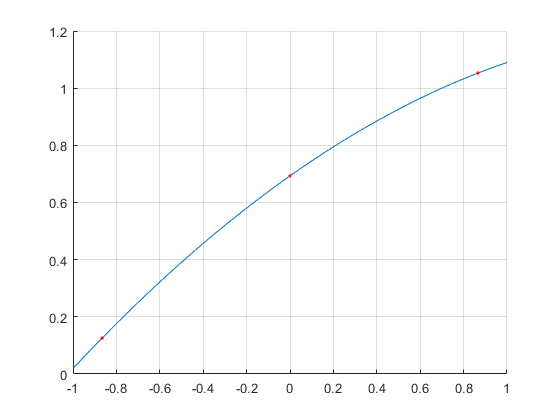

coef = newpoly(X, Y);
N = @(x) polyval(coef, x);

clf('reset')
hold on
fplot(N, [-1, 1])
plot(X, Y, '.r')
grid on
hold off


$$P\left(x\right)=C_1 \;T_1 \left(x\right)+\;\ldotp \ldotp \ldotp {+\;C}_n \;T_n \left(x\right)$$


chebyshevT(0:2, x)

$$ans = \left(\begin{array}{ccc} 1 & x & 2\,x^{2}-1 \end{array}\right)$$

Cheby = @(x) dot( C, chebyshevT(0:2, x) );

clf('reset')
hold on
fplot(Cheby, [-1, 1])

plot(X, Y, '.r')
grid on
hold off

**2. **Encuentre cotas para el máximo error en los polinomios interpolantes del ejercicio anterior en el intervalo $\left\lbrack -1,1\right\rbrack$

- 
$$|E\left(x\right)|\le \frac{1}{2^n \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


Definimos así la función error y cada uno de sus componentes:

clear
syms f(x)

f(x) = log(x + 2);

df(x) = diff(f, 2 +1)

$$df(x) = \frac{2}{{\left(x+2\right)}^{3}}$$


f = matlabFunction(f);
df = matlabFunction(df);

df(-1), df(1)

ans = 2

ans = 0.0741

E = abs( df(-1) / (2^2 * factorial(2 + 1)) )

E = 0.0833

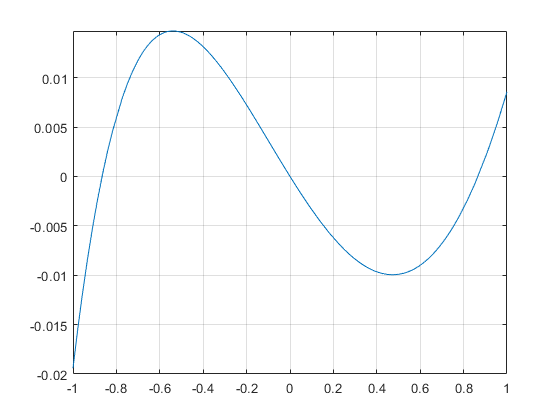

[~, X, Y] = cheby(f, 3 -1, -1, 1);
coef = newpoly(X, Y);
N = @(x) polyval(coef, x);

Err = @(x) f(x) - N(x);
fplot(Err, [-1 1])
grid on

**4. **Utilice los ceros del polinomio de Chebyshev de grado 3 trasladados al intervalo [a, b] indicado pormedio de un cambio de variable para obtener polinomios interpolantes de grado 2 para las siguientes funciones:

  **     c) **$f\left(x\right)=x\;\ln \left(x\right)\;:\;\left\lbrack 1,\;3\right\rbrack$

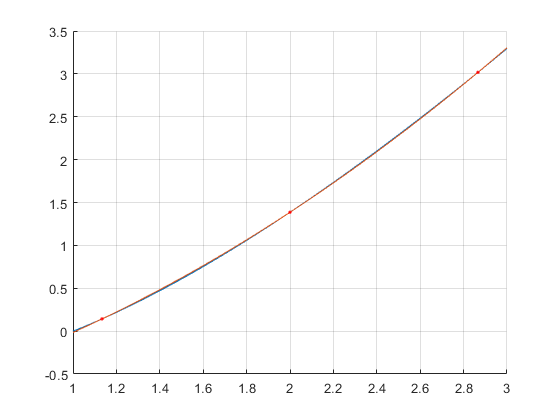

clear
syms f(x)

f(x) = x * log(x);

f = matlabFunction(f);

[~, X, Y] = cheby(f, 2, 1, 3);

C = newpoly(X, Y);

N = @(x) polyval(C, x);

clf("reset")
hold on
fplot(f, [1, 3])
fplot(N,[1, 3])
plot(X, Y, '.r')
grid on
hold off

**5. **Encuentre cotas para el máximo error en los polinomios interpolantes del ejercicio anterior en el intervalo $\left\lbrack a,b\right\rbrack$.

- 
$$|E\left(x\right)|\le \frac{2\;{\left(b-a\right)}^{n+1} }{4^{n+1} \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


Definimos así la función error y cada uno de sus componentes:

clear
syms f(x)

f(x) = x * log(x);

df(x) = diff(f, 2 + 1)

$$df(x) = -\frac{1}{x^{2}}$$

f = matlabFunction(f);
df = matlabFunction(df);
abs(df(1)), abs(df(3))

ans = 1

ans = 0.1111

E = abs( 2 * (3 - 1)^3 / ( 4^3 * factorial(3) ) * df(1) )

E = 0.0417

**6.** Encuentre los polinomios de mínimos cuadrados de grado 1, 2 y 3 para los datos de la siguiente tabla:

Gráfique los datos y los polinomios de cada uno de los grados, además cálcule el error por medio de la formula:


$$E=\sum_{j=1}^6 {\left(y_i -p_n \left(x_j \right)\right)}^2$$


clear

X = [1 1.1 1.3 1.5 1.9 2.1];
Y = [1.84 1.96 2.21 2.45 2.94 3.18];

C1 = lspoly(X, Y, 1)

C1 =     1.2196
    0.6209


C2 = lspoly(X, Y, 2)

C2 =    -0.0109
    1.2533
    0.5966


C3 = lspoly(X, Y, 3)

C3 =    -0.0100
    0.0353
    1.1850
    0.6290


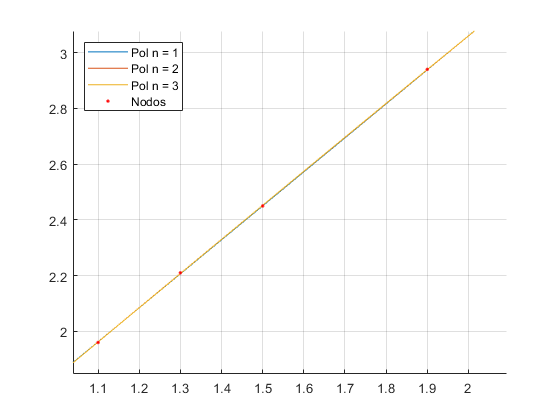

P1 = @(x) polyval(C1, x);
P2 = @(x) polyval(C2, x);
P3 = @(x) polyval(C3, x);

clf('reset')
hold on
fplot(P1, [1 2.1])
fplot(P2, [1 2.1])
fplot(P3, [1 2.1])
plot(X, Y, '.r')
legend('Pol n = 1', 'Pol n = 2', 'Pol n = 3', 'Nodos', 'Location',"northwest")
grid on


$$E=\sum_{j=1}^6 {\left(y_i -p_n \left(x_j \right)\right)}^2$$


E1 = 0;
E2 = 0;
E3 = 0;

Forma Iterativa

for j = 1:6 
    E1 = E1 + (Y(j) - P1(X(j)))^2;
    E2 = E2 + (Y(j) - P2(X(j)))^2;
    E3 = E3 + (Y(j) - P3(X(j)))^2;
end

E1, E2, E3

E1 = 2.7194e-05

E2 = 1.8015e-05

E3 = 1.7407e-05

Forma vectorizada

sum( (Y - P1(X)).^2 )

ans = 2.7194e-05

sum( (Y - P2(X)).^2 )

ans = 1.8015e-05

sum( (Y - P3(X)).^2 )

ans = 1.7407e-05